clc 
clear all

initialization of parameters

alpha = 0.95;
data_file = "data.csv";
data = readtable(data_file,Delimiter=',')

data = 603×3 table
        audio           text      response
    ______________    ________    ________

    {'hola.wav'  }    {'HOLA'}    {'HOLA'}
    {'hola1.wav' }    {'HOLA'}    {'HOLA'}
    {'hola2.wav' }    {'HOLA'}    {'HOLA'}
    {'hola3.wav' }    {'HOLA'}    {'HOLA'}
    {'hola4.wav' }    {'HOLA'}    {'HOLA'}
    {'hola5.wav' }    {'HOLA'}    {'HOLA'}
    {'hola6.wav' }    {'HOLA'}    {'HOLA'}
    {'hola7.wav' }    {'HOLA'}    {'HOLA'}
    {'hola8.wav' }    {'HOLA'}    {'HOLA'}
    {'hola9.wav' }    {'HOLA'}    {'HOLA'}
    {'hola10.wav'}    {'HOLA'}    {'HOLA'}
    {'hola11.wav'}    {'HOLA'}    {'HOLA'}
    {'hola12.wav'}    {'HOLA'}    {'HOLA'}
    {'hola13.wav'}    {'HOLA'}    {'HOLA'}
    {'hola14.wav'}    {'HOLA'}    {'HOLA'}
    {'hola15.wav'}    {'HOLA'}    {'HOLA'}


audio_names = data.audio

audio_names = 603×1 cell array
    {'hola.wav'  }
    {'hola1.wav' }
    {'hola2.wav' }
    {'hola3.wav' }
    {'hola4.wav' }
    {'hola5.wav' }
    {'hola6.wav' }
    {'hola7.wav' }
    {'hola8.wav' }
    {'hola9.wav' }
    {'hola10.wav'}
    {'hola11.wav'}
    {'hola12.wav'}
    {'hola13.wav'}
    {'hola14.wav'}
    {'hola15.wav'}
    {'hola16.wav'}
    {'hola17.wav'}
    {'hola18.wav'}
    {'hola19.wav'}
    {'hola20.wav'}
    {'hola21.wav'}
    {'hola22.wav'}
    {'hola23.wav'}
    {'hola24.wav'}
    {'hola25.wav'}
    {'hola26.wav'}
    {'hola27.wav'}
    {'hola28.wav'}
    {'hola29.wav'}


audio_content = data.text

audio_content = 603×1 cell array
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}


load data,

num_components = 4;
audios = zeros(length(audio_names),num_components);
fs = 48000;
possible_fs = [768000, 384000, 192000, 96000, 48000, 24000, 12000, 705600, 352800, 176400, 88200, 44100, 22050, 11025, 32000, 16000, 8000];
for i=1:length(audio_names)
   [audio, fs_x] = audioread(strcat("audios/",audio_names{i}));
    if(size(audio,2) > 1)
        audio = mean(audio,2);
    end
    [~, index] = min(abs(possible_fs - fs_x));
    audio = audioresample(audio,InputRate=possible_fs(index),OutputRate=fs);
    mfccs = mfcc(audio,fs);
    mfccs = reshape(mfccs,1,[]);
    centroid = spectralCentroid(audio, fs);
    centroid(isnan(centroid)) = 0;
    % Concatenar las características en un solo vector
    %#audios(i, :) = normalizeAndReduceDimension(features, 250);
    if mod(i,201) == 1 
        min_mfccss = length(mfccs);
        min_centroid = length(centroid);
        centroids = cell(201,1);
        centroids{mod(i,201)} = centroid;
    elseif mod(i,201) == 0 %cambio de audio
        if length(mfccs) < min_mfccs
            min_mfccs = length(mfccs);
        end
        if length(centroid) < min_centroid
            min_centroid = length(centroid);
        end
        centroids{201} = centroid;
        audios(i-200:i,:) = normalizeAndReduceDimension(mfccs,min_mfccs,centroids,min_centroid,num_components);
    else %llenar celdas
        if length(mfccs) < min_mfccss
            min_mfccs = length(mfccs);
        end
        if length(centroid) < min_centroid
            min_centroid = length(centroid);
        end
        centroids{mod(i,201)} = centroid;
    end
end

audios

audios =     5.5748    0.5847    5.6645   -0.2580
   -7.5383    5.7552   -0.9752   -0.1549
    6.1183   -1.0855   -3.0809    0.1617
    6.1183   -1.0855   -3.0809    0.1617
    5.5748    0.5847    5.6645   -0.2580
    6.1183   -1.0855   -3.0809    0.1617
    5.5748    0.5847    5.6645   -0.2580
    6.1183   -1.0855   -3.0809    0.1617
  -11.3901   -6.6083    0.5306   -1.1205
    5.5748    0.5847    5.6645   -0.2580


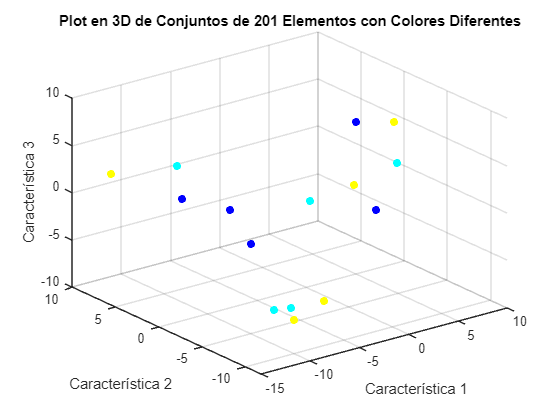

% Supongamos que tu matriz de características se llama 'audios' y tiene las características en las columnas
% Ajusta 'audios' según el nombre real de tu matriz

% Crear una figura
figure;

% Número de conjuntos de 201 elementos
numSets = size(audios, 1) / 201;

% Colores para cada conjunto
colors = jet(numSets);

% Iterar sobre cada conjunto de 201 elementos
for i = 1:numSets
    startIndex = (i - 1) * 201 + 1;
    endIndex = i * 201;
    
    % Plotear los puntos del conjunto actual en 3D con un color diferente
    scatter3(audios(startIndex:endIndex, 1), audios(startIndex:endIndex, 2), audios(startIndex:endIndex, 3), 'filled', 'MarkerFaceColor', colors(i, :));
    hold on;  % Mantener el gráfico actual para superponer los conjuntos
end

% Etiquetas y título
xlabel('Característica 1');
ylabel('Característica 2');
zlabel('Característica 3');
title('Plot en 3D de Conjuntos de 201 Elementos con Colores Diferentes');

% Mostrar cuadrícula
grid on;

function reducedFeatures = normalizeAndReduceDimension(mfcc,min_mfccs,centroids,min_centroid, targetLength)
    mfcc_matrix = zeros([201,min_mfccs]);
    centroids_matrix = zeros([201,min_centroid]);
    for i=1:201
        mfcc_matrix(i,:) = mfcc(1:min_mfccs);
        centroid = centroids{i};
        centroids_matrix(i,:) = centroid(1:min_centroid);
    end
    features = horzcat(mfcc_matrix,centroids_matrix);
    % Normalizar los datos
    normalizedFeatures = zscore(features);

    % Reducir la dimensión utilizando PCA
    [coeff, ~, ~, ~, explained] = pca(normalizedFeatures);
    numComponents = find(cumsum(explained) >= 99, 1);
    reducedFeatures = normalizedFeatures * coeff(:, 1:numComponents);
    % Ajustar la longitud del vector de características a la deseada
    if size(reducedFeatures, 2) < targetLength
        % Si es más corto, rellenar con ceros
        reducedFeatures = horzcat(reducedFeatures,zeros([201,targetLength-size(reducedFeatures,2)]));
    else
        % Si es más largo, truncar
        reducedFeatures = reducedFeatures(:, 1:targetLength);
    end
end
